clear
addpath control_holistic_inverse_dynamics
load("trajectories.mat");
modelName = 'CONTROL_HOLIST_ID';

load_system(modelName);
out = sim(modelName);

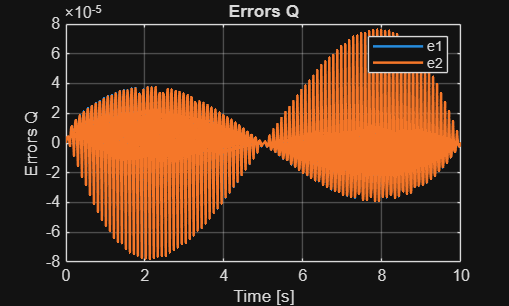

errors_Q  = out.errors_Q;
errors_dQ  = out.errors_dQ;
voltage   = out.voltage;

errors_Q_data = squeeze(errors_Q.Data);
errors_dQ_data = squeeze(errors_dQ.Data);
voltage_data  = squeeze(voltage.Data);

figure
plot(errors_Q.Time, errors_Q_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Errors Q')
title('Errors Q')
legend('e1', 'e2')

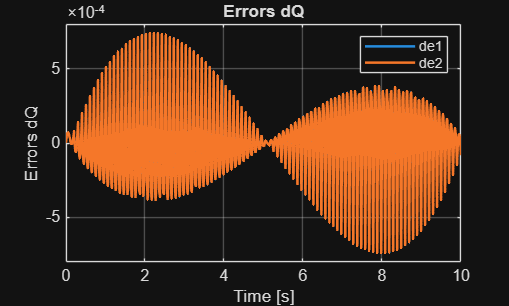


figure
plot(errors_dQ.Time, errors_dQ_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Errors dQ')
title('Errors dQ')
legend('de1', 'de2')

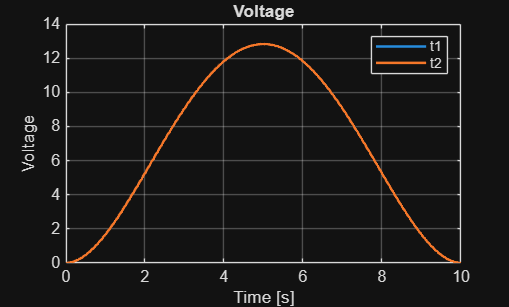


figure
plot(voltage.Time, voltage_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Voltage')
title('Voltage')
legend('t1', 't2')